# Plot Gas Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

countries = string(table2array(readtable("../data/gPrices.xlsx", "Sheet", "countries", "ReadVariableNames", false)));
prices = table2array(readtable("../data/gPrices.xlsx", "Sheet", "prices", "ReadVariableNames", false));
ctry = "Germany";
% Find the index value for ctry
idx = strcmp(ctry, countries);
ctryPrices = prices(:, idx);

## Task 1 

for k = 1:length(countries)
    c(k, :) = polyfit(ctryPrices, prices(:, k), 1);
end

Plot linear fit.

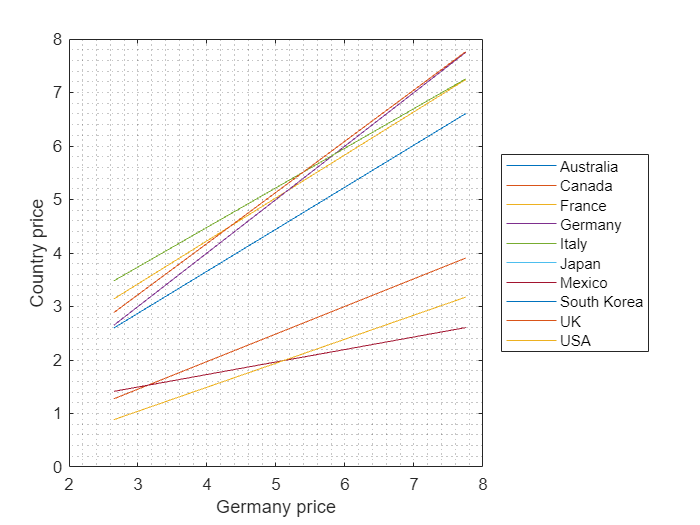

linfit = ctryPrices.*c(:, 1)' + c(:, 2)';
plot(ctryPrices, linfit)
grid minor
legend(countries, "Location", "eastoutside")
xlabel(ctry + " price")
ylabel("Country price")